%% Hyperparameters
% Global parameters used in preprocessing

GAIN_VALS = [10, 20, 30, 40, 50];

% Spectrogram and signal processing parameters
NFFT = 128;            % Number of FFT points
SAMPLE_RATE = 3840;    % Sample rate in Hz
LOW_CUTOFF = 10;       % Low cutoff frequency in Hz
HIGH_CUTOFF = 450;     % High cutoff frequency in Hz

These are the hyperparameters used in this test of different gain values

%% Loading data
% Open the .txt containing the sensor output
% and then store the values for plotting

raw_data = {};  % Initialize a cell array to store the data

for i = GAIN_VALS
    % Read the data from the text file
    filename = sprintf('../sensor_test/gain%d.txt', i);
    fid = fopen(filename, 'r');
    temp = textscan(fid, '%s', 30000, 'Delimiter', '\n');  % Read the first 30,000 lines
    fclose(fid);
    
    % Convert the data from cell to array
    temp = temp{1};  % Extract the data from the cell
    num_points = length(temp);  % Get the number of points
    
    % Preallocate temp_data array
    temp_data = zeros(num_points, 1);  % Create an array of zeros
    
    % Convert string values to numbers
    for c = 1:num_points
        temp_data(c) = str2double(temp{c});  % Convert each value to double
    end
    
    % Append temp_data to raw_data
    raw_data{end+1} = temp_data;
end

Now we can preprocess

preprocessed_data = {};
DOWNSCALE_FACTOR = 19;
for gain_index = 1:length(raw_data)
    k = raw_data{gain_index};
    % Process the data for each channel
    k = downsample(k, DOWNSCALE_FACTOR)
    temp_data = bandpass(k, [LOW_CUTOFF HIGH_CUTOFF], SAMPLE_RATE);
    preprocessed_data{end+1} = temp_data;
end

k =    510
   509
   513
   510
   510
   513
   510
   512
   513
   510


k =    510
   511
   512
   511
   511
   511
   511
   511
   511
   511


k =    512
   511
   511
   511
   511
   511
   511
   511
   511
   510


k =    511
   510
   511
   511
   511
   511
   510
   512
   510
   511


k =    511
   512
   511
   511
   511
   510
   512
   510
   511
   510


Now we can plot

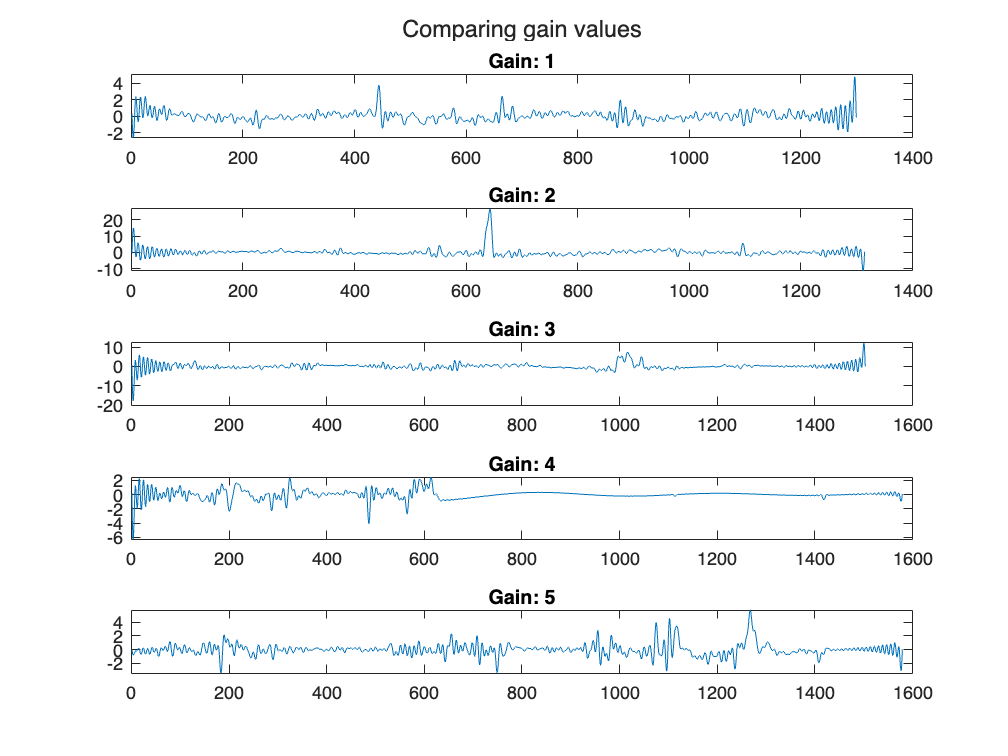

% Create a figure with subplots
num_subplots = length(raw_data);
figure;
tiledlayout(num_subplots, 1);  % Create a tiled layout for the subplots
sgtitle('Comparing gain values');  % Super title for the entire figure
% Loop through the raw_data and plot each one in a separate subplot
for c = 1:num_subplots
    nexttile;
    plot(preprocessed_data{c});  % Plot the data
    title(sprintf('Gain: %d', c));  % Set title for each subplot
end